% experiment3.mlx
% Transfer learning with Resnet50

clc; clear; close all;

gpu = gpuDevice

gpu =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce RTX 3080'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
             DriverVersion: 11.4000
            ToolkitVersion: 11
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 1.0501e+10
           AvailableMemory: 8.3353e+09
       MultiprocessorCount: 68
              ClockRateKHz: 1800000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


%224x224
DatasetPath= '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/224x224_SIMETRICA'

DatasetPath = '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/224x224_SIMETRICA'

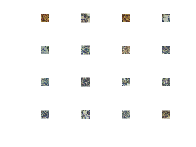

imds = imageDatastore(DatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');


[imdsTrain, imdsVal, imdsTest] = splitEachLabel(imds, 0.7, 0.2, 0.1,"randomized");
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end



net = resnet50;
%analyzeNetwork(net)

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


lgraph = layerGraph(net);
numClasses = numel(categories(imdsTrain.Labels))

numClasses = 3

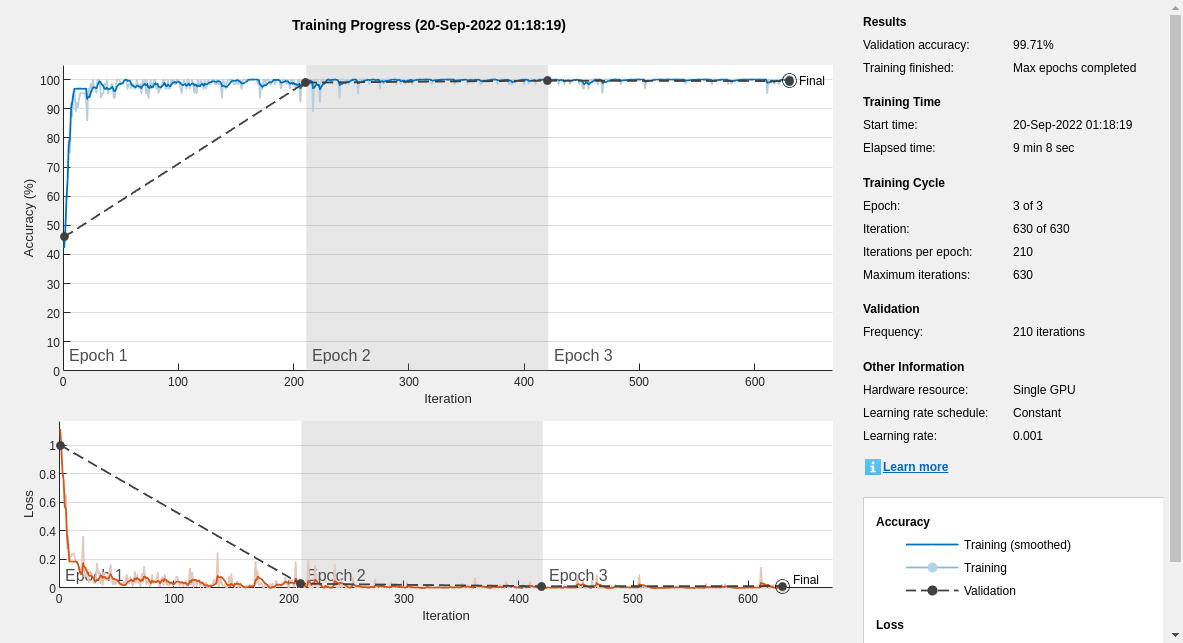


newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name', 'Steel Feature Learner', ...
    'WeightLearnRateFactor', 10, ...
    'BiasLearnRateFactor', 10);

lgraph = replaceLayer(lgraph,'fc1000', newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', newClassLayer);
Network_Architecture = layerGraph(net);

Minibatch_Size = 64;
validationFrequency = floor(numel(imdsTrain.Files)/Minibatch_Size);
Training_Options = trainingOptions('sgdm', ...
    'MiniBatchSize', Minibatch_Size, ...
    'MaxEpochs', 3, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsVal, ...
    'ValidationFrequency', validationFrequency, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

[net tr]= trainNetwork(imdsTrain, lgraph, Training_Options);


% Accuracy (Val)
[YPred,probs] = classify(net,imdsVal);
accuracyVal = mean(YPred == imdsVal.Labels)

accuracyVal = 0.9971

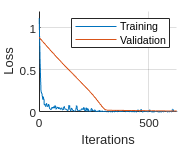


%Plot train 
%Loss
figure;
x = [1:630];
yl = tr.TrainingLoss;
yvl = tr.ValidationLoss;
%yvl = rmmissing(yvl); %Remove NaN
plot(x, smooth(yl));
hold on;
plot(x, smooth(yvl));
set(gca, 'box', 'off')
legend('Training','Validation');
axis( [0 630 0 1.2] );
grid on;
xlabel('Iterations');
ylabel('Loss');

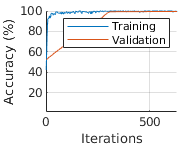


%Accuracy
figure;
x = [1:630];
y = tr.TrainingAccuracy;
yv = tr.ValidationAccuracy;
%yi = smooth(y);

plot(x, smooth(y));
hold on;
plot(x, smooth(yv));
set(gca, 'box', 'off')
legend('Training','Validation');
axis( [  0     630    1    100 ] );
grid on;
xlabel('Iterations');
ylabel('Accuracy (%)');

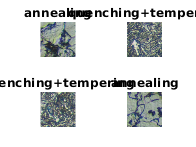


%TEST

[YPredTest,scores] = classify(net,imdsTest);
idx = randperm(numel(imdsTest.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    %label = YPred(idx(i));
    label = YPredTest(idx(i));
    title(string(label));
end


YTest = imdsTest.Labels;
accuracyTest = mean(YPredTest == YTest)

accuracyTest = 0.9948

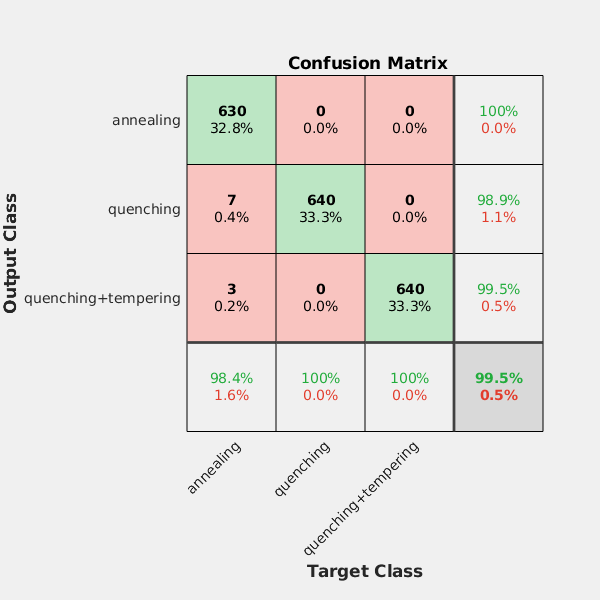

plotconfusion(YTest, YPredTest)

T = cMetrics(YTest, YPredTest)

Accuracy = 99.74%

T = 5×5 table
                          Precision    Recall      Fallout     Specificity      F1   
                          _________    _______    _________    ___________    _______

    recocido               0.99174           1    0.0037879      0.99621      0.99585
    temple                       1     0.99242            0            1       0.9962
    temple+revenido400           1           1            0            1            1
    Avg                    0.99725     0.99747    0.0012626      0.99874      0.99735
    WgtAvg                 0.99742      0.9974    0.0011837      0.99882       0.9974


writetable(T,'metricasResnet5.xls')

% For Matthew correlation coefficient
confM = confusionmat(YPredTest, YTest);
multiMetrics = multiclass_metrics_special(confM);

save('experiment3Workspace.mat')